close all
clear
clc

定义符号

syms n x w

定义宽为10的离散时间矩形脉冲，对其做z变换

x = heaviside(n) - heaviside(n-10);
Zx = ztrans(x);

将z变换中的z替换为ejw，即得到离散时间傅里叶变换DTFT

DTFTx = subs(Zx,'z',exp(1j*w));

定义z平面上的采样点，分别由模的采样和辐角的采样组合得到

r = [0.02:0.02:1.5];
w1 = [0.02:0.02:2*pi+0.04];
z1 = exp(1j*w1)'*r;

取z平面采样点上的z变换的值

Zx1 = double(subs(Zx,'z',z1)); 

取单位圆上辐角采样的DTFT的值

DTFTx1 = double(subs(DTFTx,'w',w1));

准备绘图

figure, box on, hold on, grid on;

对z变换值截断

Zx2 = max(min(real(Zx1),20),-5);

分别绘制z变换的曲面和DTFT的线条

surf(real(z1),imag(z1),Zx2,'linestyle','none');
plot3(cos(w1),sin(w1),real(DTFTx1),'k','LineWidth',2);
xlabel('z_{real}','FontSize',14);
ylabel('z_{imag}','FontSize',14);
zlabel('z(x) & DTFT(x)','FontSize',14);
set(gca,'FontSize',14);
set(gca,'XLim',[-1.5,1.5],'YLim',[-1.5,1.5]);

调整视角

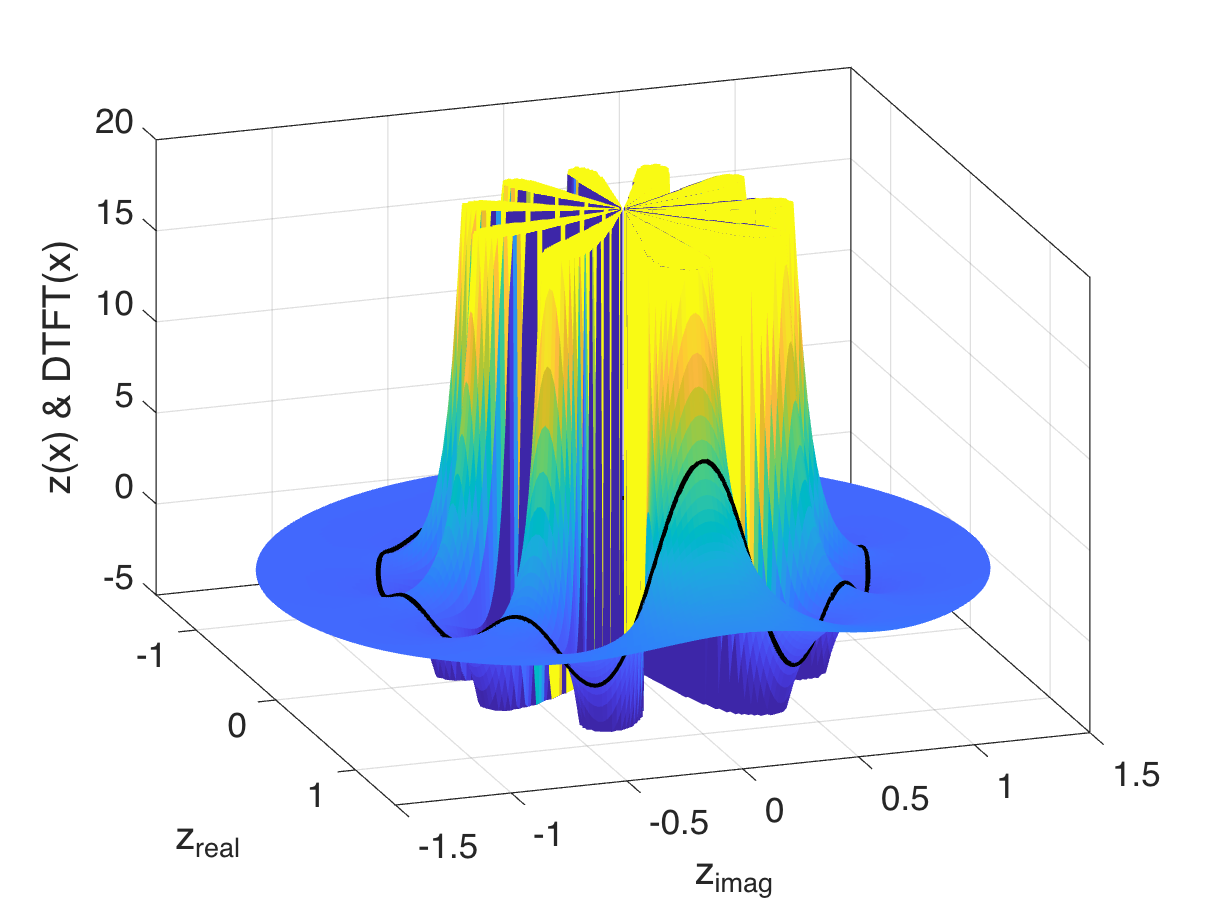

view(71,26);